a) Produce 3 histograms for M, M_tilde, and zoomed in M_tilde

load dataset/sparseCoding.mat

%Generate M_tilde
M_tilde = H*M*H';

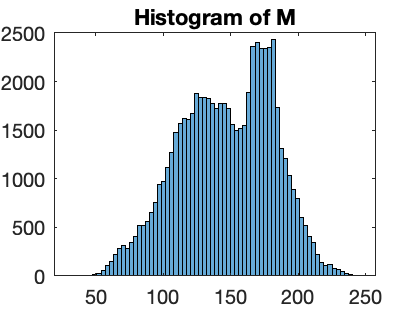

%Create histogram
histogram(M)
title('Histogram of M')

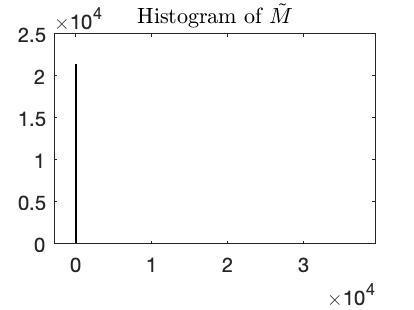


histogram(M_tilde)
title('Histogram of $\tilde{M}$', 'Interpreter','latex') 


histogram(M_tilde(M_tilde > -10 & M_tilde < 10))
title('Zoomed In Histogram of $\tilde{M}$', 'Interpreter','latex') 


text = ['Number of zero elements in M_tilde: ', num2str(sum(sum(M_tilde == 0)))];
disp(text);

Number of zero elements in M_tilde: 229



text = ['Number of zero elements in M: ', num2str(sum(sum(M == 0)))];
disp(text);

Number of zero elements in M: 0


d) Compute optimal X* for lambda = 30

lambda = 30;
X_star = zeros(256);

%compute X_star
for i = 1:256
    for j = 1:256
        if M_tilde(i,j) >= lambda
            X_star(i,j) = M_tilde(i,j) - lambda;
        elseif M_tilde(i,j) <= -lambda
            X_star(i,j) = M_tilde(i,j) + lambda;
        else
            X_star(i,j) = 0;
        end
    end
end

%compute compression factor
compression_factor = sum(sum(X_star ~= 0)) / 256^2;
disp(['Compression factor: ' num2str(compression_factor)]);

Compression factor: 0.11534



%conduct inverse wavelet transform
M_hat = H'*X_star*H;

%compute MSE
MSE = (sum(sum((M - M_hat).^2)))/(256^2);
disp(['MSE: ' num2str(MSE)]);

MSE: 195.3582


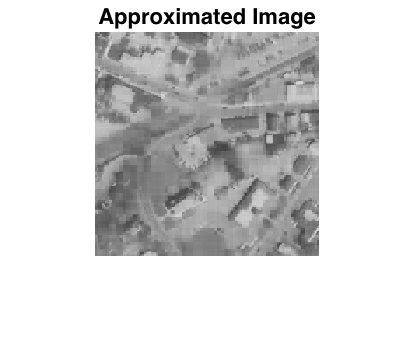


%produce histogram for M_hat
imshow(M_hat/255);
title('Approximated Image');

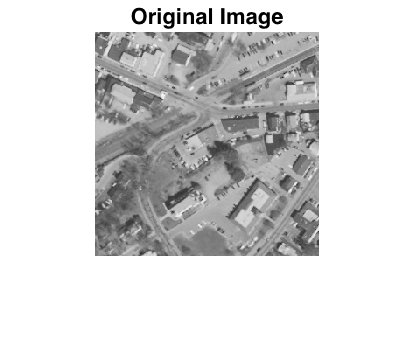

imshow(M/255);
title('Original Image');

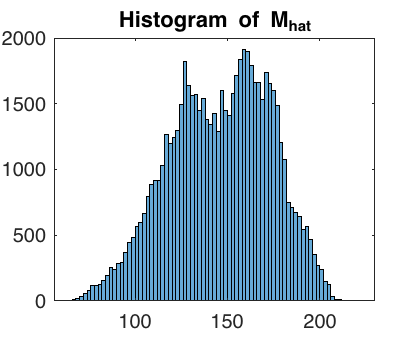


%produce histogram
histogram(M_hat);
title('Histogram of M_{hat}')

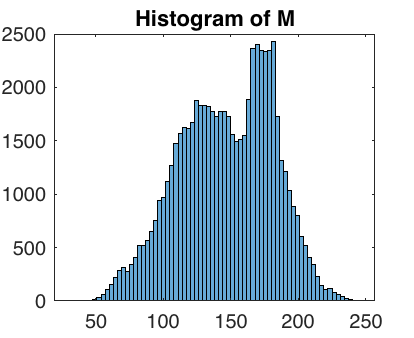


histogram(M);
title('Histogram of M')

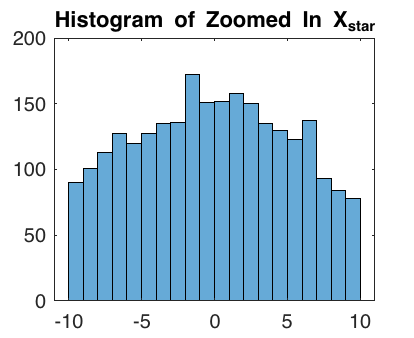


histogram(X_star(X_star ~= 0 & X_star > -10 & X_star < 10));
title('Histogram of Zoomed In X_{star}')

M_hat isn't too far from original M but higher energy bins are clipped.

e) Repeat for lambda = 10 and 90.

lambda = 10;
X_star = zeros(256);

%compute X_star
for i = 1:256
    for j = 1:256
        if M_tilde(i,j) >= lambda
            X_star(i,j) = M_tilde(i,j) - lambda;
        elseif M_tilde(i,j) <= -lambda
            X_star(i,j) = M_tilde(i,j) + lambda;
        else
            X_star(i,j) = 0;
        end
    end
end

%compute compression factor
compression_factor = sum(sum(X_star ~= 0)) / 256^2;
disp(['Compression factor: ' num2str(compression_factor)]);

Compression factor: 0.351



%conduct inverse wavelet transform
M_hat = H'*X_star*H;

%compute MSE
MSE = (sum(sum((M - M_hat).^2)))/(256^2);
disp(['MSE: ' num2str(MSE)]);

MSE: 48.3425


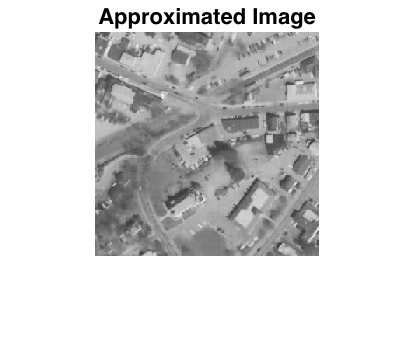


%produce histogram for M_hat
imshow(M_hat/255);
title('Approximated Image');

imshow(M/255);
title('Original Image');

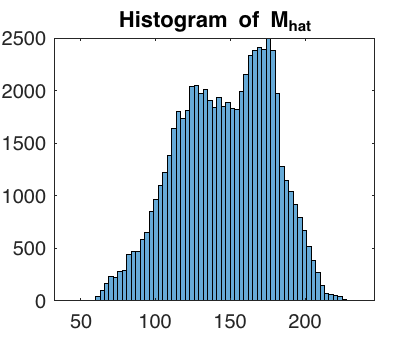


%produce histogram
histogram(M_hat);
title('Histogram of M_{hat}')


histogram(M);
title('Histogram of M')

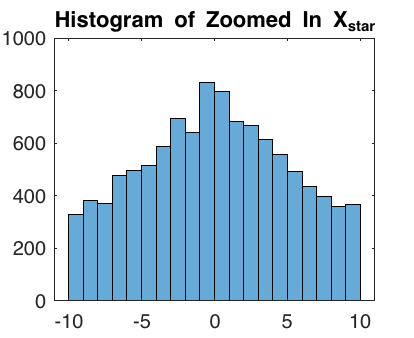


histogram(X_star(X_star ~= 0 & X_star > -10 & X_star < 10));
title('Histogram of Zoomed In X_{star}')

lambda = 90;
X_star = zeros(256);

%compute X_star
for i = 1:256
    for j = 1:256
        if M_tilde(i,j) >= lambda
            X_star(i,j) = M_tilde(i,j) - lambda;
        elseif M_tilde(i,j) <= -lambda
            X_star(i,j) = M_tilde(i,j) + lambda;
        else
            X_star(i,j) = 0;
        end
    end
end

%compute compression factor
compression_factor = sum(sum(X_star ~= 0)) / 256^2;
disp(['Compression factor: ' num2str(compression_factor)]);

Compression factor: 0.019592



%conduct inverse wavelet transform
M_hat = H'*X_star*H;

%compute MSE
MSE = (sum(sum((M - M_hat).^2)))/(256^2);
disp(['MSE: ' num2str(MSE)]);

MSE: 494.0172


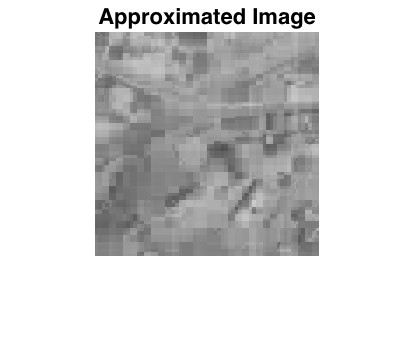


%produce histogram for M_hat
imshow(M_hat/255);
title('Approximated Image');

imshow(M/255);
title('Original Image');

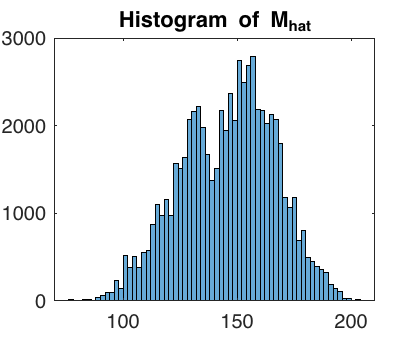


%produce histogram
histogram(M_hat);
title('Histogram of M_{hat}')


histogram(M);
title('Histogram of M')

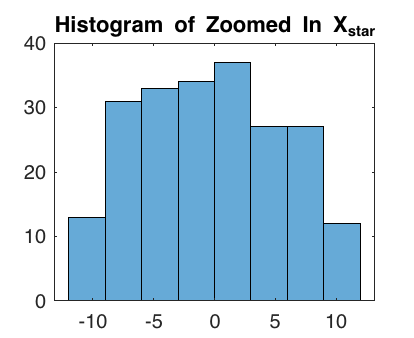


histogram(X_star(X_star ~= 0 & X_star > -10 & X_star < 10));
title('Histogram of Zoomed In X_{star}')

For lower lambda, more data is retained. Hence the better looking reconstruction.